 Loading the battery dataset

%% STEP 1: Download and Load Battery Dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

%% STEP 2: Parse and Segment Data
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable = 'Voltage';
bParser.TimeVariable = 'DateTime';
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  
segmentedRawDataTable = segmentData(bParser);

%% STEP 3: Extract All Valid "Charge" Data for Cycle 1
chargingData = segmentedRawDataTable(...
    segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge", :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));


CC-CV Region Separation

% Time relative to start of charge phase
t = chargingData.TimeInSeconds;
V = chargingData.Voltage;
I = chargingData.Current;

%% STEP 2: Compute Derivative dV/dt (Rate of Voltage Change)
% Numerical derivative w.r.t time in seconds
dVdt = gradient(V) ./ gradient(t); 

%% STEP 3: Identify Transition Point (CC to CV)
% Method 1: Find where Voltage reaches within 0.5% of Vmax (3.6 V)
vCutoff = 0.995 * max(V); 
transitionIdx = find(V >= vCutoff, 1, 'first');

% Method 2: Optional confirmation via dV/dt threshold
% When CV starts, dV/dt plateaus near 0 (< 0.0001 V/s)
confirmIdx = find(dVdt(10:end) <= 0.0001, 1, 'first') + 9;

% Transition timestamp and voltage/current values
t_trans = t(transitionIdx);
V_trans = V(transitionIdx);
I_trans = I(transitionIdx);

%% STEP 4: Split Data into CC and CV Tables
ccData = chargingData(1:transitionIdx, :);
cvData = chargingData(transitionIdx:end, :);

fprintf('--- CC-CV Region Separation Results ---\n');

--- CC-CV Region Separation Results ---


fprintf('Transition Time: %.2f seconds (%.2f mins)\n', t_trans, t_trans/60);

Transition Time: 1212.15 seconds (20.20 mins)


fprintf('Transition Voltage: %.4f V\n', V_trans);

Transition Voltage: 3.5829 V


fprintf('Transition Current: %.4f A\n', I_trans);

Transition Current: 1.1001 A


fprintf('dV/dt at Transition: %.6f V/s\n', dVdt(transitionIdx));

dV/dt at Transition: 0.001906 V/s


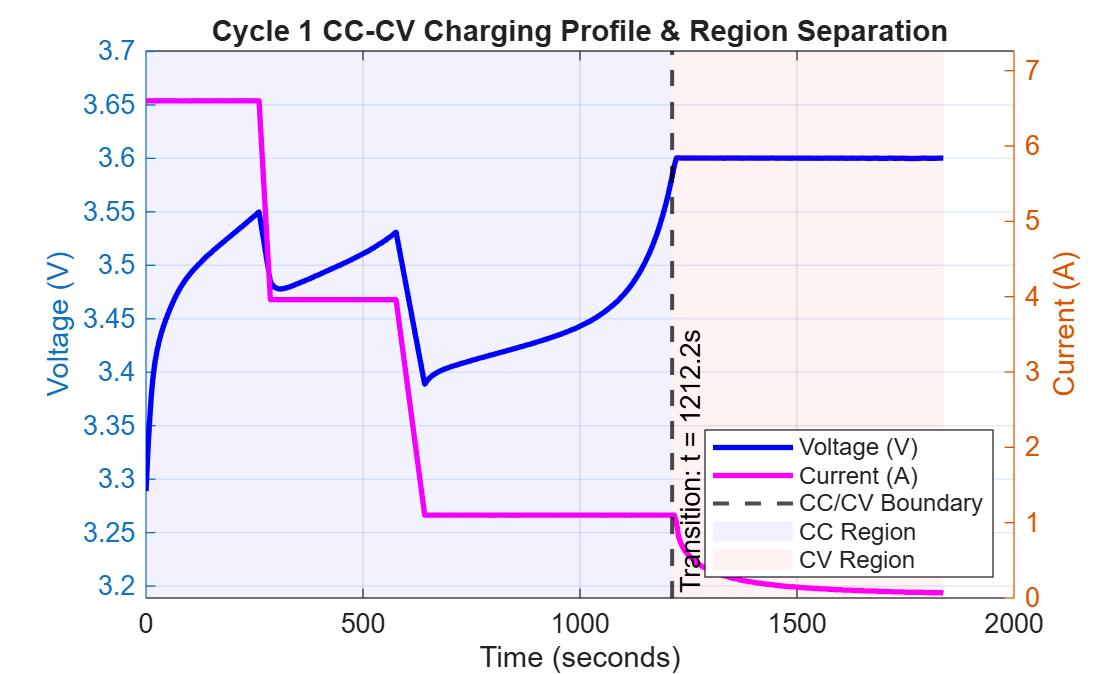


%% STEP 5: Plot Dual-Axis CC/CV Charging Profile
figure('Name', 'CC-CV Charging Phase Analysis');

% Left Y-Axis: Voltage
yyaxis left
plot(t, V, '-b', 'LineWidth', 2, 'DisplayName', 'Voltage (V)');
ylabel('Voltage (V)');
ylim([min(V)-0.1, max(V)+0.1]);

hold on;

% Right Y-Axis: Current
yyaxis right
plot(t, I, '-m', 'LineWidth', 2, 'DisplayName', 'Current (A)');
ylabel('Current (A)');
ylim([0, max(I)*1.1]);

% Mark Transition Line & Shading
xline(t_trans, '--k', 'LineWidth', 1.5, ...
    'Label', sprintf('Transition: t = %.1fs', t_trans), ...
    'LabelVerticalAlignment', 'bottom', ...
    'DisplayName', 'CC/CV Boundary');

% Highlight CC and CV Regions
patch([0 t_trans t_trans 0], [0 0 max(I)*1.1 max(I)*1.1], 'b', ...
    'FaceAlpha', 0.05, 'EdgeColor', 'none', 'DisplayName', 'CC Region');
patch([t_trans max(t) max(t) t_trans], [0 0 max(I)*1.1 max(I)*1.1], 'r', ...
    'FaceAlpha', 0.05, 'EdgeColor', 'none', 'DisplayName', 'CV Region');

hold off;

% Graph Formatting
xlabel('Time (seconds)');
title('Cycle 1 CC-CV Charging Profile & Region Separation');
grid on;
legend('Location', 'southeast');

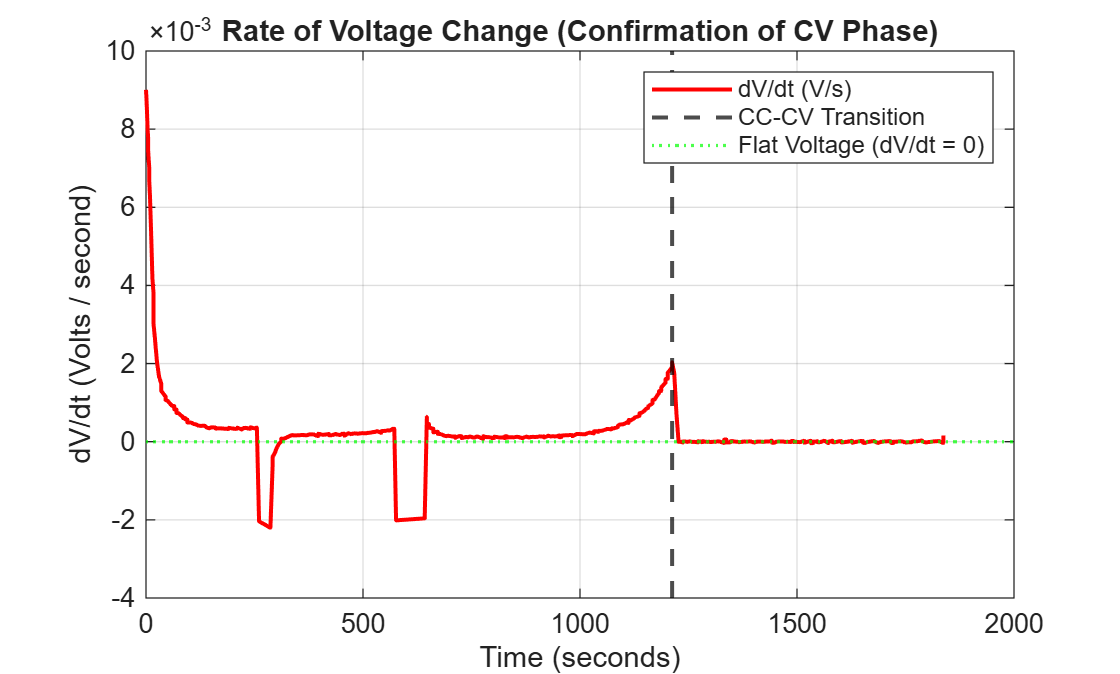


%% STEP 6: Plot Voltage Derivative (dV/dt) Confirmation
figure('Name', 'Voltage Derivative Analysis');
plot(t, dVdt, '-r', 'LineWidth', 1.5, 'DisplayName', 'dV/dt (V/s)');
hold on;
xline(t_trans, '--k', 'LineWidth', 1.5, 'DisplayName', 'CC-CV Transition');
yline(0, ':g', 'LineWidth', 1.2, 'DisplayName', 'Flat Voltage (dV/dt = 0)');
hold off;

xlabel('Time (seconds)');
ylabel('dV/dt (Volts / second)');
title('Rate of Voltage Change (Confirmation of CV Phase)');
grid on;
legend('Location', 'northeast');